## Lab 2

*Name: Joshua Yap*

*Lab Partner: Dane Thorn*

### Problem 1

This lab explores gamma-ray detection in the atmosphere. The background cosmic rays provide a noise term that follows a Poisson distribution. In order to detect a gamma-ray source, we need to determine the probability that the background gives us a reading as signal-like or more signal-like than our measurement.

Assume that in 1 day, the average cosmic-ray background is 3, and the average number of gamma-rays emitted by the hypothetical source is 13.

Below we first plot what the background distribution looks like for one day.

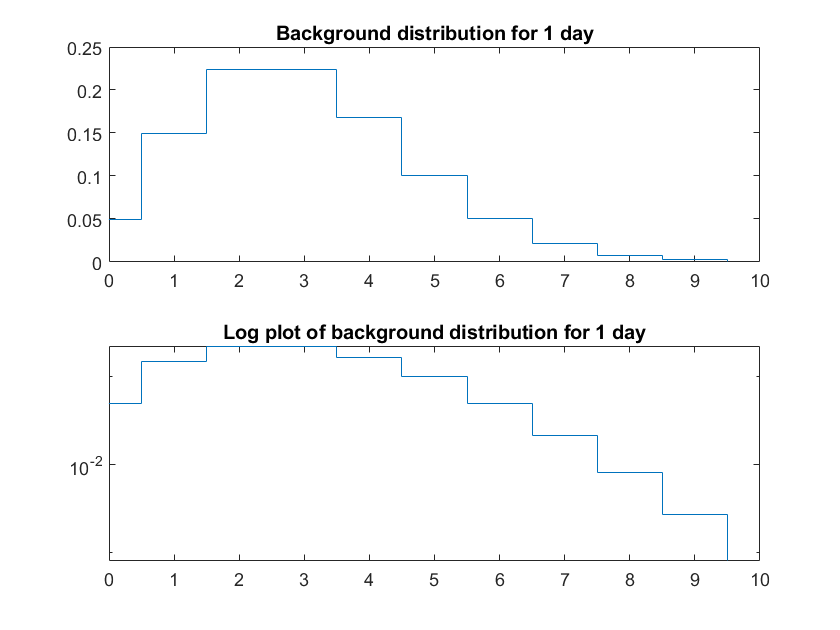

clear all; close all; clc
xspan = [0:10];
lambda = 3;
pd = makedist('Poisson',lambda);
subplot(2,1,1)
stairs(xspan-0.5,pdf(pd,xspan))
xlim([0 10])
title('Background distribution for 1 day')

subplot(2,1,2)
stairs(xspan-0.5,pdf(pd,xspan))
set(gca,'YScale','log')
xlim([0 10])
title('Log plot of background distribution for 1 day')

Now we investigate the effect of summing the distribution over a number of days.

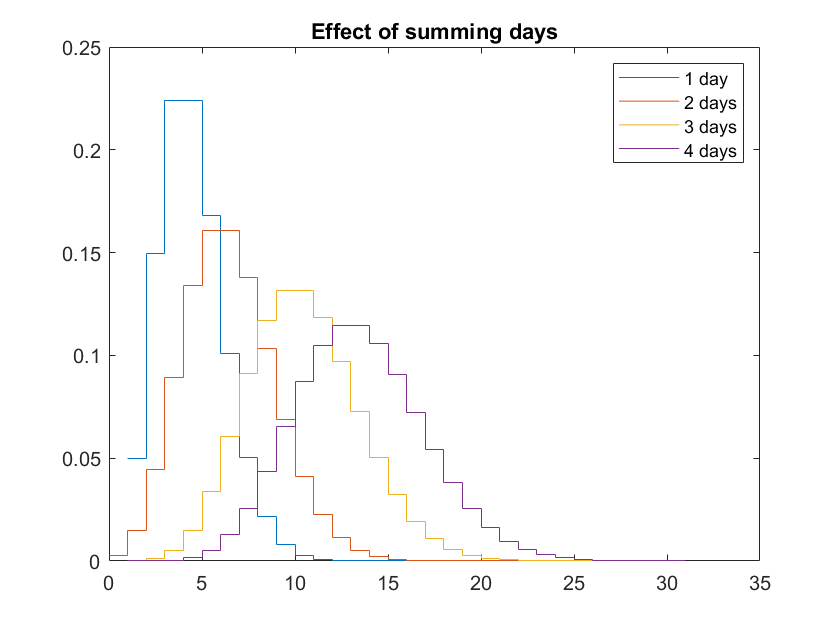

figure
pd_2 = makedist('Poisson',lambda*2);
pd_3 = makedist('Poisson',lambda*3);
pd_4 = makedist('Poisson',lambda*4);
x_sum = [0:30];
stairs(pdf(pd,x_sum))
hold on
stairs(x_sum,pdf(pd_2,x_sum))
stairs(pdf(pd_3,x_sum))
stairs(pdf(pd_4,x_sum))
title('Effect of summing days')
legend('1 day','2 days','3 days','4 days')

The distribution gets wider and is centered around a larger value. This makes sense because as we increase the time interval over which we are observing events, we expect to see more events.

Below we look at the sum over 5 days.

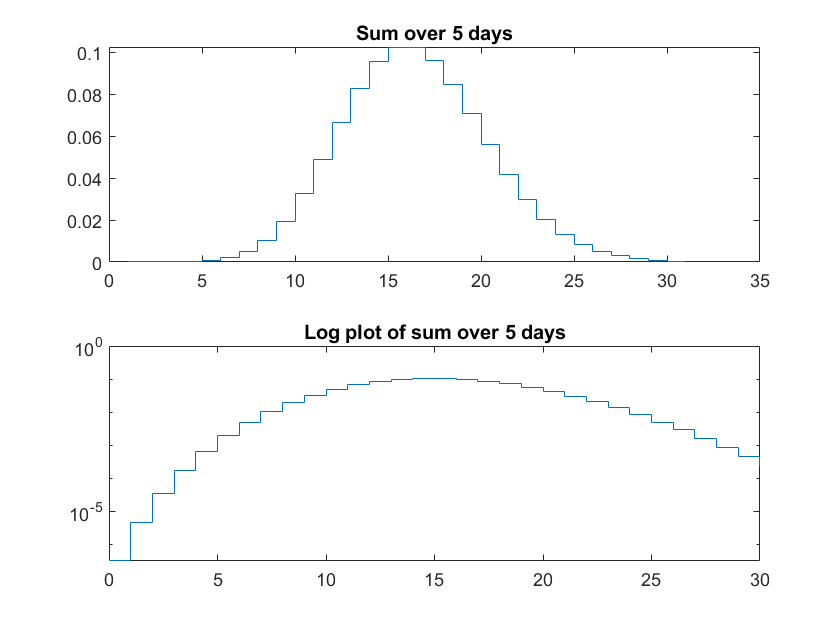

figure
pd_5 = makedist('Poisson',lambda*5);
subplot(2,1,1)
stairs(pdf(pd_5,x_sum))
title('Sum over 5 days')

subplot(2,1,2)
stairs(x_sum,pdf(pd_5,x_sum))
set(gca,'YScale','log')
title('Log plot of sum over 5 days')

The log plot shows the same general shape as the one observed for the 1-day distribution, albeit more spread out. It would make sense for the sum to be a Poisson distribution because we are merely increasing the time interval in which to observe events. The average number of events in the extended period should be proportional to the average number of events in a day.

Mathematically, suppose $X~\textrm{Poisson}\left(\lambda \right)$. From *proofwiki.org*, the probability generating function of $X$ is given by

$\prod_X \left(s\right)=e^{-\lambda \;\left(1-s\right)}$.

If we have 2 independent time intervals, the resulting probability generating function is


$$\prod_{X+X} \left(s\right)=\prod_X \left(s\right)\prod_X \left(s\right)$$



$$=e^{-\lambda \;\left(1-s\right)} e^{-\lambda \;\left(1-s\right)}$$



$$=e^{-\left(2\lambda \;\right)\left(1-s\right)}$$


This is the probability generating function for a Poisson distribution with a mean of $2\lambda \;$. Therefore any sum of Poisson distributions is also a Poisson distribution with the mean equal to the sum of the means of the original distributions.

We now explore how the probability distribution evolves as we average the days. Plotted below are some averages.

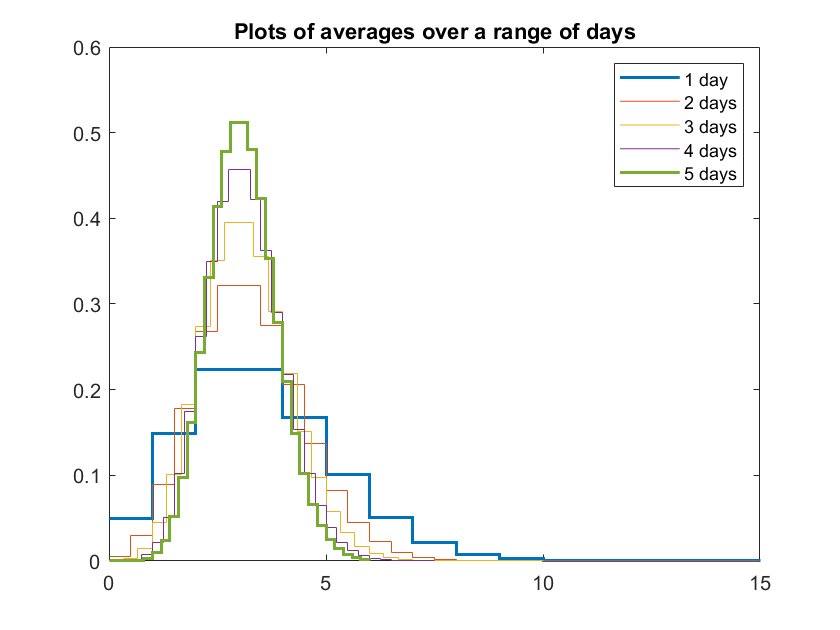

figure
stairs(x_sum,pdf(pd,x_sum),'LineWidth',1.5)
hold on
stairs(x_sum/2,2*pdf(pd_2,x_sum))
stairs(x_sum/3,3*pdf(pd_3,x_sum))
stairs(x_sum/4,4*pdf(pd_4,x_sum))
stairs(x_sum/5,5*pdf(pd_5,x_sum),'LineWidth',1.5)
xlim([0 15])
title('Plots of averages over a range of days')
legend('1 day','2 days','3 days','4 days','5 days')
hold off

The more days over which we take the average, the narrower the distribution becomes. The mean remains the same but we can see that the standard deviation decreases. To generate the plots above, we shrank the x-axes and extended the y-axes to maintain normalization. The right tail is still longer than the left, so it remains a Poisson distribution but looks more like a Gaussian now. It is clearer in the log plot below where I just plot the 1-day and 5-day averages.

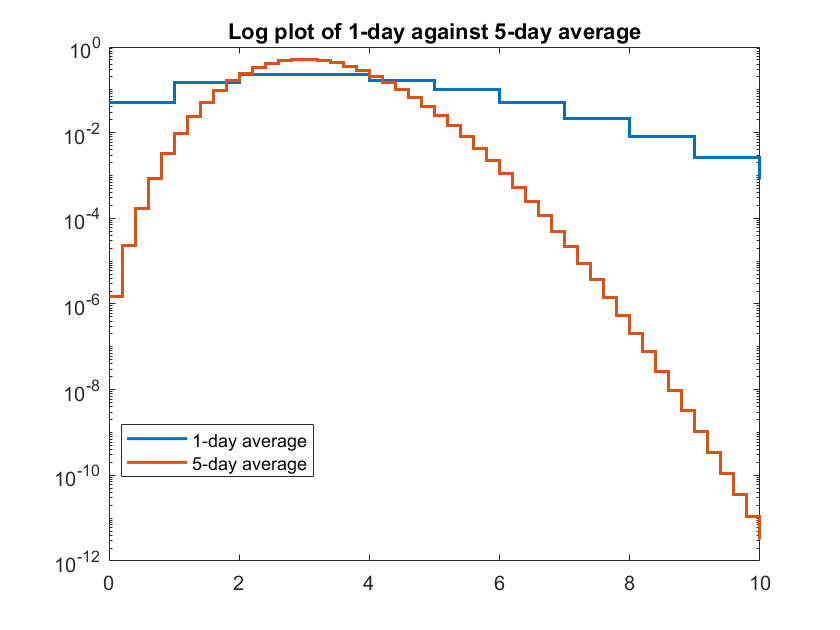

figure
x_1day = [0:10];
x_5day = [0:50];
stairs(x_1day,pdf(pd,x_1day),'LineWidth',1.5)
hold on
stairs(x_5day/5,5*pdf(pd_5,x_5day),'LineWidth',1.5)
set(gca,'YScale','log')
title('Log plot of 1-day against 5-day average')
legend('1-day average','5-day average','Location','best')

The log plot of the 5-day average now has a more parabolic shape. This agrees with the central limit theorem, which states that as more independent random variables are added, the normalized distribution approaches that of a normal distribution even if the variables are not normally distributed. In this case, we can say that averaging over more days allows us to approximate the distribution as a normal distribution.

Now we continue with the hypothetical gamma-ray source. Suppose we collected data over 10 days and saw 130 gamma rays from our source. We want to know the 'sigma' of our observation. Our approach is outlined below:

1. Sum the background distribution over 10 days. This means that the mean of the resulting distribution would be 30.

2. Integrate the resulting pdf from 130 to $\infty$.

3. Convert the probability obtained to a sigma value.

prob = poisscdf(130,30,'upper');
sig = norminv(1-prob);
disp(['Probability = ' string(prob); ...
    'Sigma = ' string(sig)])

    "Probability = "    "4.5476e-42"
    "Sigma = "          "Inf"       



These values seem pretty extreme, so we plot the distribution on a log scale to verify them.

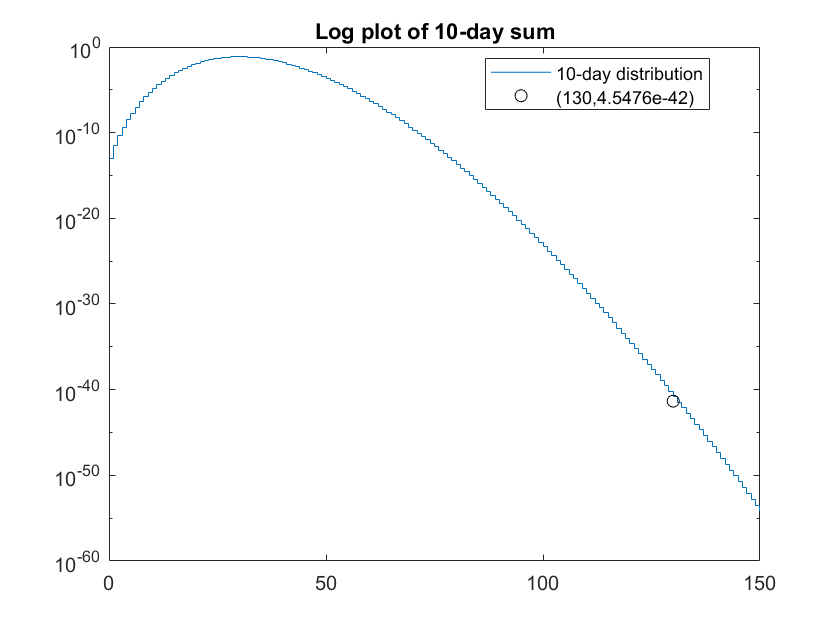

figure
x_10day = [0:2000];
pd_10 = makedist('Poisson',lambda*10);
stairs(x_10day,pdf(pd_10,x_10day))
hold on
plot(130,prob,'ko')
set(gca,'YScale','log')
xlim([0 150])
title('Log plot of 10-day sum')
legend('10-day distribution','(130,4.5476e-42)','Location','best')
hold off

The marker is slightly below the distribution, so it is reasonable that the integral of everything right of the marker adds up to the y-value of the marker. The probability is dropping rapidly at this point.

In this section, we pick a Rayleigh distribution and observe how it changes as we average it over more intervals.

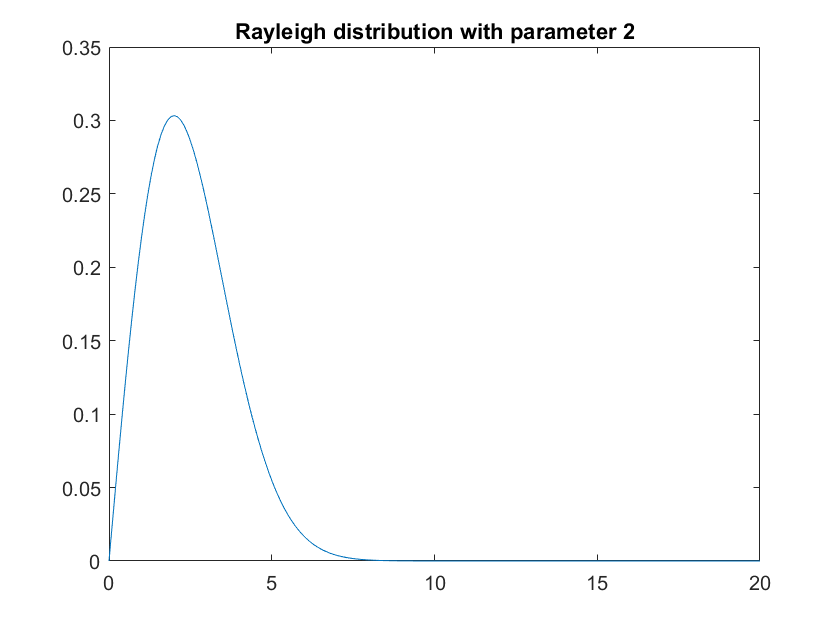

dx = 0.1;
range = 20;
x = [0:dx:range];
ray = raylpdf(x,2);
figure
plot(x,ray)
title('Rayleigh distribution with parameter 2')

Now we want to find out what the distribution looks like as it is averaged over more intervals. To do this, we convolve the distribution with itself multiple times.

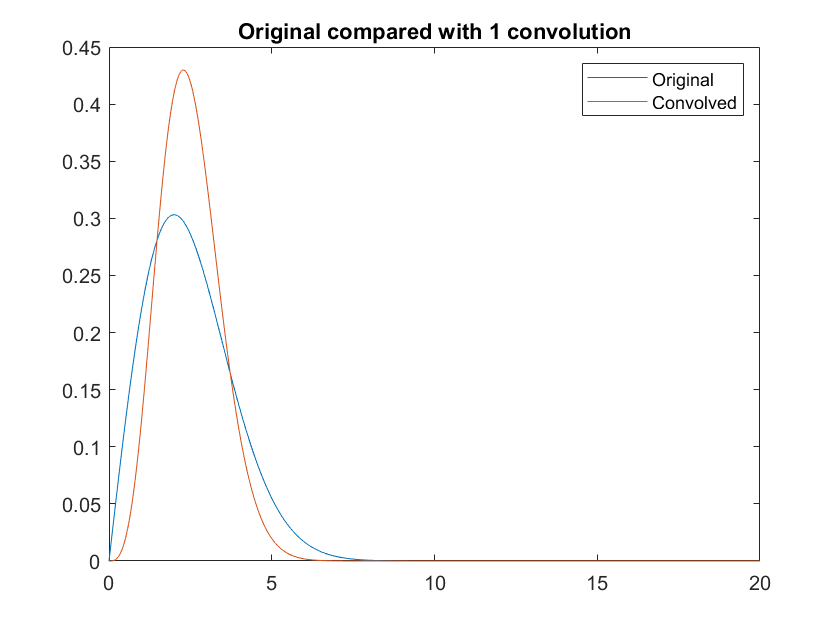

ray2 = conv(ray,ray);
% Normalize ray2
ray2 = ray2/(dx*sum(ray2));
figure
x2 = [0:dx:2*range];
plot(x,ray,x2/2,2*ray2)
title('Original compared with 1 convolution')
legend('Original','Convolved')

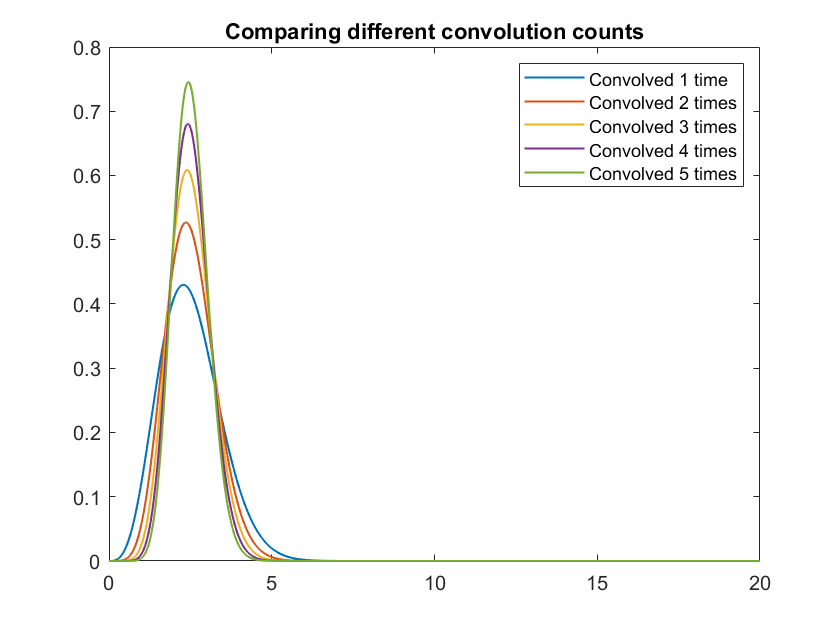

temp = ray;
figure
for j=[1:5]
    x_temp = [0:dx:range*(j+1)];
    temp = conv(ray,temp);
    temp_norm = temp/(dx*sum(temp));
    plot(x_temp/(j+1),(j+1)*temp_norm,'LineWidth',1)
    hold on
end
title('Comparing different convolution counts')
legend('Convolved 1 time','Convolved 2 times','Convolved 3 times', ...
    'Convolved 4 times','Convolved 5 times')
hold off

The more times we convolve the distribution, the denser and more Gaussian-looking the distribution becomes. The peak gets higher and the tails start to equalize in shape.

In order to see how close to a Gaussian distribution we get, we compare them on a log plot below.

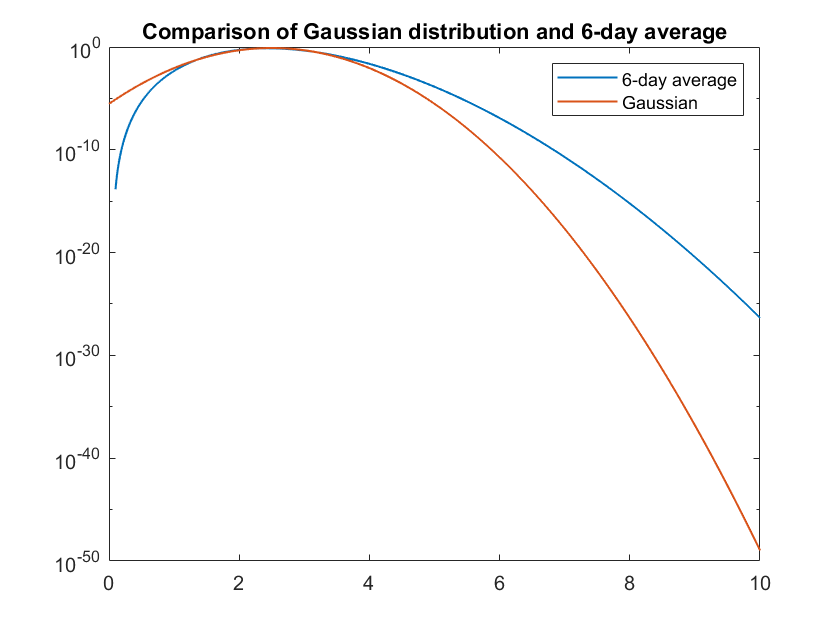

% Define normal distribution
norm_test = normpdf(x_temp/(j+1),2.5,0.5);
plot(x_temp/(j+1),(j+1)*temp_norm,x_temp/(j+1),norm_test,'LineWidth',1)
set(gca,'YScale','log')
title('Comparison of Gaussian distribution and 6-day average')
legend('6-day average','Gaussian')
xlim([0,10])

At the end of 5 convolutions, the resulting distribution still looks fairly different from a Gaussian one. We convolve it more below to see how much it takes to be approximately Gaussian.

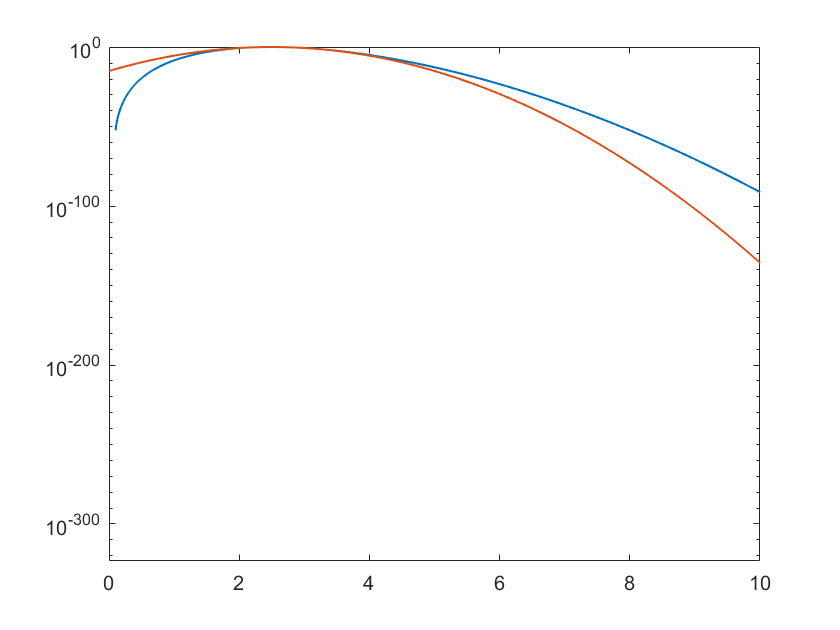

temp = ray;
for j=[1:20]
    %x_temp = [0:dx:range*(j+1)];
    temp = conv(ray,temp);
    %temp_norm = temp/(dx*sum(temp));
    %plot(x_temp/(j+1),(j+1)*temp_norm,'LineWidth',1)
    %hold on
end
x_j = [0:dx:range*(j+1)];
temp_j = temp/(dx*sum(temp));
norm_j = normpdf(x_j/(j+1),2.5,0.3);
figure
plot(x_j/(j+1),(j+1)*temp_j,x_j/(j+1),norm_j,'LineWidth',1)
set(gca,'YScale','log')
xlim([0 10])

After 20 convolutions, the resulting distribution matches a Gaussian distribution better as evidenced by the log plot. We plot the distributions on a linear scale below. They appear to lie on top of each other with minor differences.

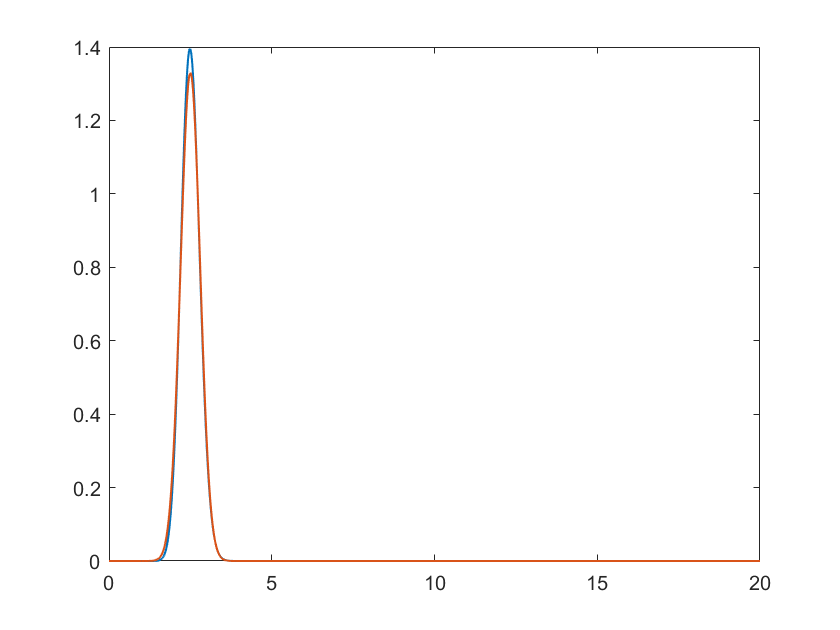

plot(x_j/(j+1),(j+1)*temp_j,x_j/(j+1),norm_j,'LineWidth',1)

How well we need our average to match a Gaussian distribution depends on the purposes for which we need the distribution. A sensitive experiment or calculation may need it to match better, so we may need to perform more convolutions.

The next part of the lab simulates determining the significance of a detection of optical counterparts of a gravity wave signal. Suppose we have an alert from LIGO and SWIFT gives us a precise location, so we take an image of that part of the sky. We know what pixel to look in because of SWIFT's accuracy.

Suppose also that by looking at the other pixels in the image, we determine the width of the background Gaussian distribution to be 0.5. Assuming we see a signal of strength 3.1, what is the significance of our detection?

This is a fairly straightforward problem to solve. We need to do the integral

$\int_{3\ldotp 1}^{\infty } \mathrm{pdf}\;\mathrm{dx}$,

where our pdf is computed in Matlab with parameters $\mu =0$ and $\sigma =0\ldotp 5$.

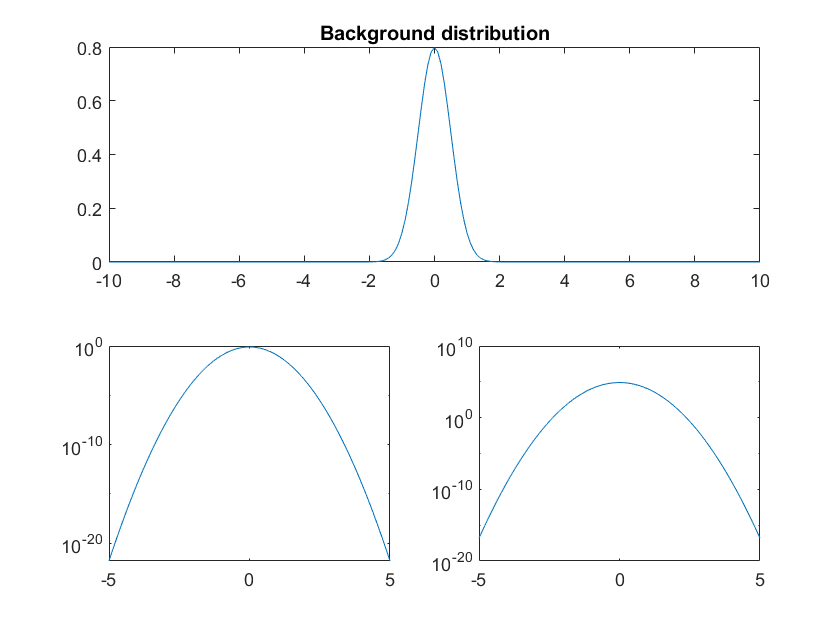

x_img = [-10:0.1:10];
img_dist = normpdf(x_img,0,0.5);
subplot(2,1,1)
plot(x_img,img_dist)
title('Background distribution')

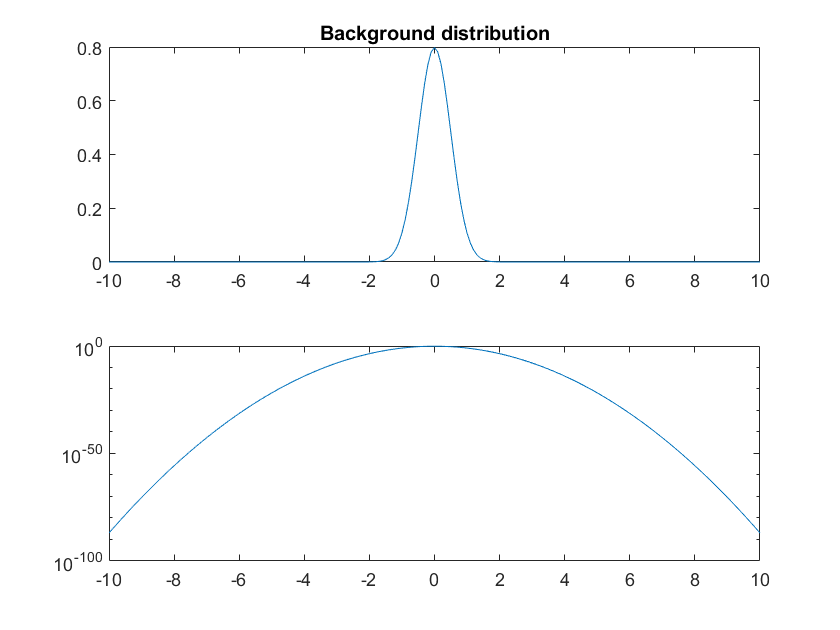


subplot(2,1,2)
plot(x_img,img_dist)
set(gca,'YScale','log')

Now we take the integral of the distribution from 3.1 upwards to get the probability and convert that to a sigma value.

p_signal = normcdf(3.1,0,0.5,'upper');
sig_signal = norminv(1-p_signal);
disp(table(p_signal,sig_signal,'VariableNames',{'Probability','Sigma'}))

    Probability    Sigma
    ___________    _____

    2.8232e-10      6.2 



With a significance of 6.2$\sigma$, **we can claim a discovery**.

Now suppose our alert from LIGO is unaccompanied by a detection from SWIFT. We know which region of the sky to look in but not the pixel. If we have 10k pixels, we need to determine a probability distribution for the background.

Statistical question in words

If the background of a single pixel is Gaussian distributed with a mean of 0 and sigma 0.5, what is the probability that a set of 10k such pixels with no signal will give us the same value or greater than the the brightest candidate signal?

Graphically, to find the distribution of the new background, we just take the original background distribution in the first part and shift it up by 10k.

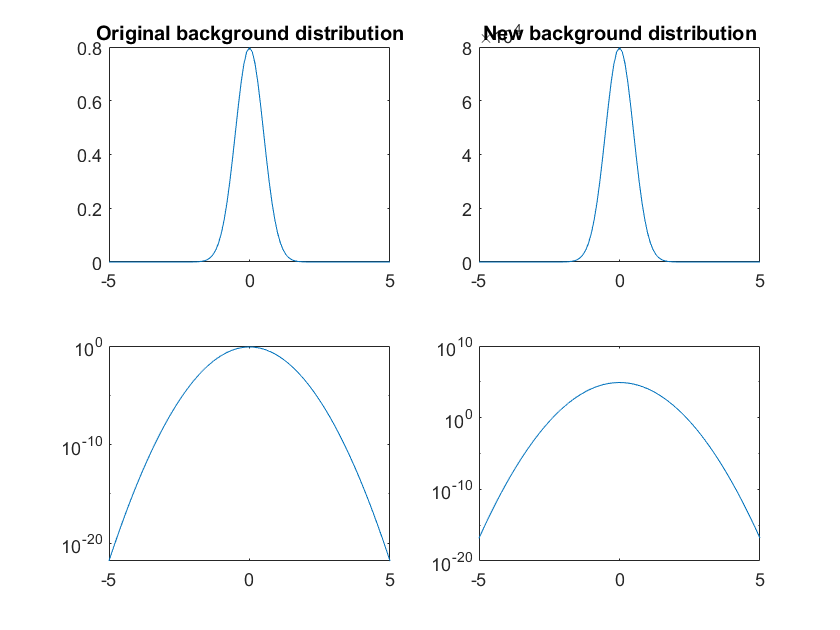

numPixels = 10e4;
backg_dist = numPixels*img_dist;
figure
subplot(2,2,1)
plot(x_img,img_dist)
title('Original background distribution')
xlim([-5,5])

subplot(2,2,3)
plot(x_img,img_dist)
set(gca,'YScale','log')
xlim([-5,5])

subplot(2,2,2)
plot(x_img,backg_dist)
title('New background distribution')
xlim([-5,5])

subplot(2,2,4)
plot(x_img,backg_dist)
set(gca,'YScale','log')
xlim([-5,5])

Now assume that our brightest candidate signal has the same value of 3.1 as in the first part. We want to compute the significance of this detection against the new background distribution.

ans = 7.8137